Johnny Vastola Math 131 Worksheet 7

1.

a.

p = @(x) polyval([1 0 0 0 0 -1], x);
X=[-2 -1 0 1 2 3];
Y = p(X);
b=linterp_bary(X,Y,-3)

b = -244.0000

p(-3)

ans = -244

b.

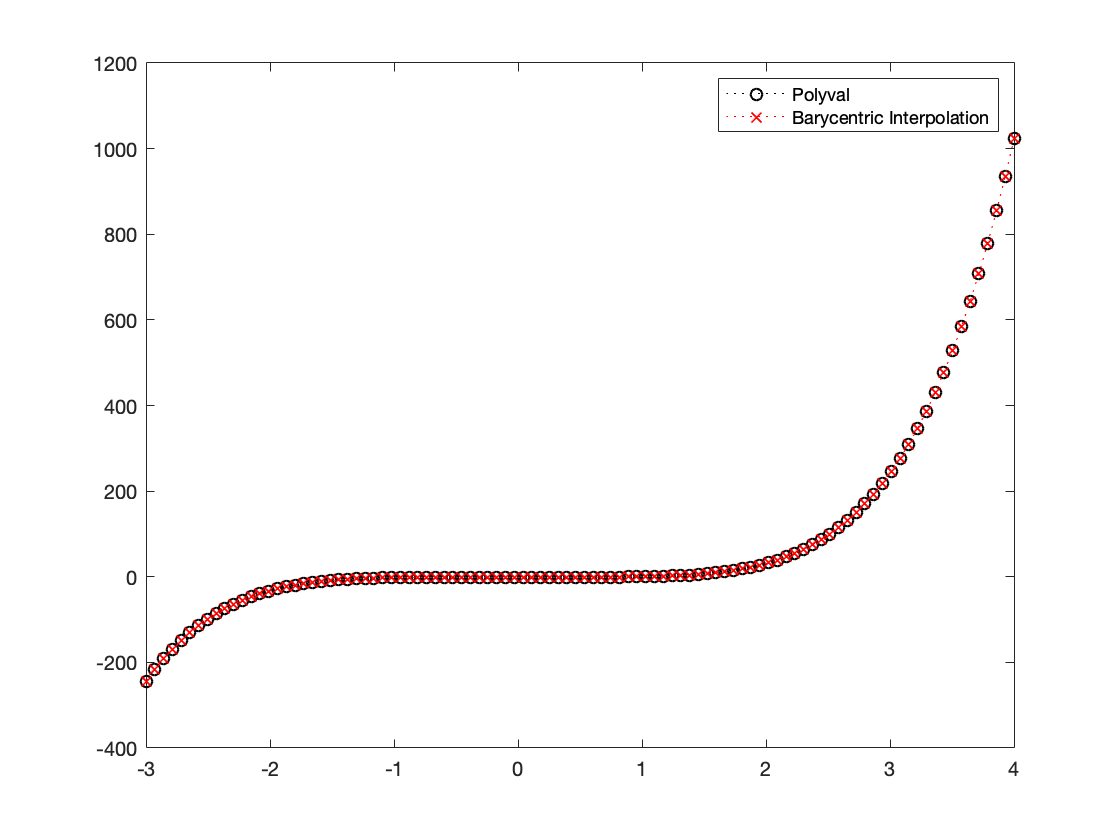

x = linspace(min(X)-1, max(X)+1, 100);
plot(x, p(x),'ko:', x, linterp_bary(X, Y, x),'rx:');legend({'Polyval', 'Barycentric Interpolation'})

Helper Functions

function y = linterp_bary(X,Y,x)
    n=length(X);
    w=ones(n,size(x,2));
    for i =1:n
        for j=1:n
            if i~=j
                w(i,:)=w(i,:).*(X(i)-X(j));
            end
        end
    end
w=1./w;
for i=1:n
    for j=1:length(x)
    t(i,:)=w(i,:)./(x(j)-X(i));
    end
end
a=0;b=0;
for i = 1:n
   for j = 1:n
       a = a + (w(i, :) ./ (x - X(i))) * Y(i);
       b = b + (w(i, :) ./ (x - X(i)));
   end
end
    y = a./b;

end